camera = webcam

camera =   webcam with properties:

                    Name: 'USB2.0 VGA UVC WebCam'
    AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
              Resolution: '640x480'
                     Hue: 50
                   Gamma: 50
        WhiteBalanceMode: 'auto'
            ExposureMode: 'auto'
            WhiteBalance: 4500
              Saturation: 50
               Sharpness: 50
              Brightness: 50
                Contrast: 50
                Exposure: -6


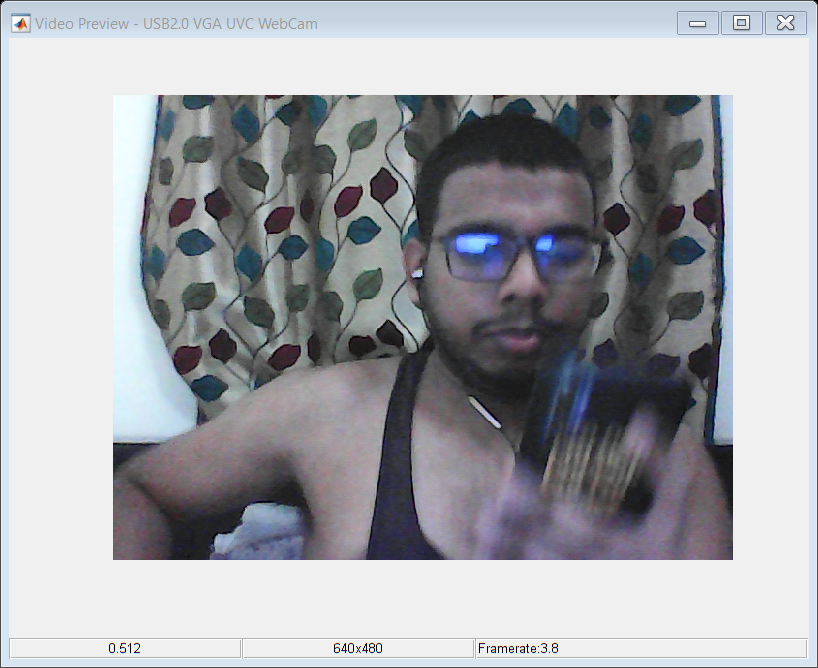

vid =   Image with properties:

           CData: [480×640×3 double]
    CDataMapping: 'direct'

  Show all properties


I =   Image with properties:

           CData: [480×640×3 double]
    CDataMapping: 'direct'

  Show all properties


Error using vision.CascadeObjectDetector/validateInputsImpl (line 338)
Expected input number 2 to be one of these types:

uint8, uint16, double, single, int16

Instead its type was matlab.graphics.primitive.Image.

nnet = alexnet;


while true
    vid=preview(camera)
    I = vid
    FDetect = vision.CascadeObjectDetector;
BB = step(FDetect,I);

hold on
for i=1:size(BB,1)
    rectangle('Position',BB(i,:),'LineWidth',1,'LineStyle','-','EdgeColor','b');
end

hold off;

end       

    imshow('Camera',gray)
    
clear('camera');